**Image Convolution, Filtering, and Deblurring Practice Notebook**

**Kuan-Min Lee**

**Image Convolution:**

**Basic Theory Explanation:**

2D Image convolution can be defined as the following equation:

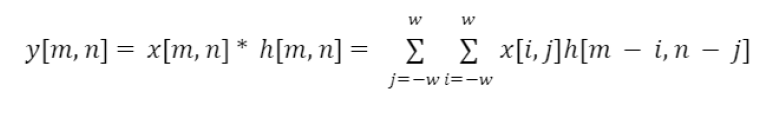

where y is the output image, x is the input image, and h is the convolution kernel that is implemented into the function.

**Demonstration:**

**Default Setting Testing:**

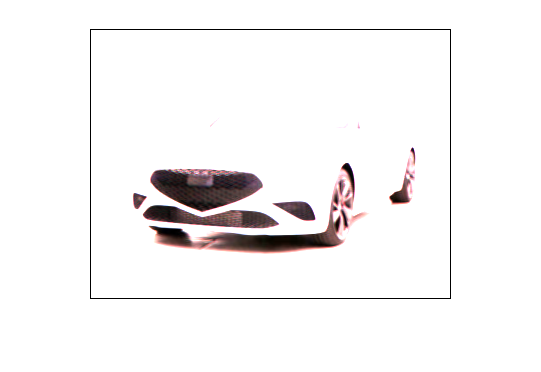

clear all
car_img=imread("car.jpg");
conv_car_img=convol_img(car_img,3);
figure(1);
imshow(uint8(conv_car_img));

**Assigned Kernel Testing:**

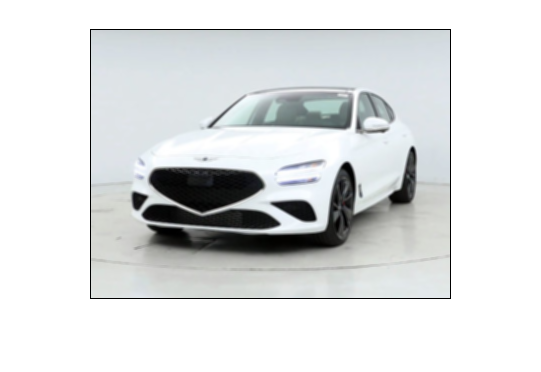

assign_kern=[1/9 1/9 1/9;...
             1/9 1/9 1/9;...
             1/9 1/9 1/9];
conv_car_img2=convol_img(car_img,3,'kernel',assign_kern);
figure(2);
imshow(uint8(conv_car_img2));

**Assigned Stride Testing:**

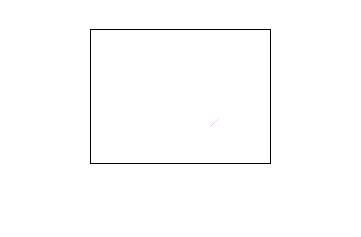

assign_stride=2;
conv_car_img3=convol_img(car_img,3,'stride',assign_stride);
figure(3);
imshow(conv_car_img3);

**Assigned Type Testing:**

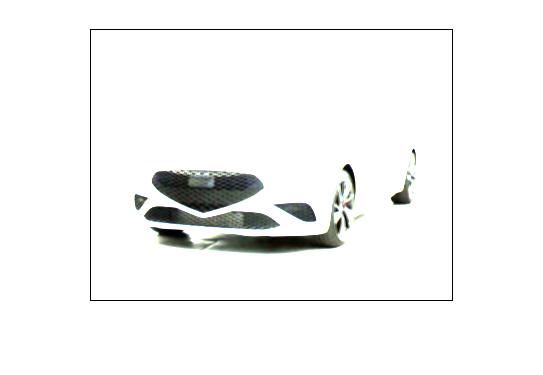

assign_type="same";
conv_car_img4=convol_img(car_img,3,'type',assign_type);
figure(4);
imshow(uint8(conv_car_img4));